# Funciones de Impulso Respuesta

**Nombre: **Valentina Andrade

**Profesor: **Alexandre Janiak                             ** Ayudantes: **Pablo Vega y Bianca Hincapié

clear;
close all;
% Global settings
warning('off'); % warnings about rank 
figure('Renderer', 'painters', 'Position', [10 10 900 600]); % figures size

En esta pregunta se estudiarpa superficialmente las Funciones de Impulso Respuesta, aplicación utilizada en series de tiempo que permiten comprender cuanto afecta un shock puramente transitorio al estado estacionario de una serie

Una forma de entender en qué consiste esta aplicación implicarecordar un proceso autoregresivo de orden 1 AR(1) del tipo

                     $x_t =\phi \;x_{t-1} +\epsilon_t$                                   (1)

Donde $\epsilon_t ~N\left(0,{\sigma^2 }_{\epsilon } \right)$ es un ruido blanco. Se dice que la serie es estacionaria cuando $|\phi \;|<1$, es decirm la serie converge a un valor de estado estacionario. La velocidad de convergencia de la serie depende del valor de $\phi$, por lo cual mientras este valor sea más cercano a 1, más lenti será su retorno al estado estacionario. Por el contrario, cuando $|\phi \;|$ es un valor cercano a cero, el proceso converge rápidamente al estado estacionario. Además se dice que hay una raíz unitaria cuando $\phi =1$.

## Contexto

Imagine dos series idénticas que describen un proceso AR(1) descrito por la  ecuación (1). Vamos a perturbar una de las dos series en un momento t, sumando un shock de magnitud $\alpha \;$al residuo $\epsilon^{\frac{1}{t}}$ de la serie. El resto de los periodos permanece igual, es decir, los residuos de la serie serán iguales expcepto en el periodo perturbado. Dado que las series eran idénticas antes de la perturbación, tenemos la serie y su **contrafactual, **por lo cual podemos **conocer la magnitud del efecto del shock transitorio restando ambas series. **

(a) Simule una serie AR(1) idéntica a (1) de 500 periodos con $\phi =0\ldotp 9$. De la misma forma simule la misma serie, pero ahora pertúrbela con un shock transitorio $\epsilon =1$ en el periodo $t=0$. Grafique la $\textrm{IRF}$. 

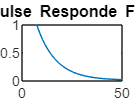

time = 500; %500 periodos
phi = 0.9; % persistencia
error = randn(time,1); % mean = 0, sd = 1
% Primera serie
x1 = NaN*ones(time,1); % Serie 1
x1(1) = 0 + error(1);
for t = 2:time
x1(t)= phi*x1(t-1) + error(t);
end

figure(1)
plot(x1)
title({'Figura 1. AR(1) sin shock'})

%Segunda serie
x2 = NaN*ones(time,1); % Serie 2
x2(1) = 0 + 1; % error 
for t = 2:time
x2(t)= phi*x2(t-1) + error(t);
end
figure(2)
plot(x2)
title({'Figura 2. AR(1) con shock'})


%%Graficar IRF
figure(3)
plot(x2-x1)
xlim([0 50])
ylim([0 1])
title({'Figura 3. Impulse Responde Function \phi =0.9'})
hold off

(b) Construya un subplot para distintos coeficientes autoregresivos $\phi \;\epsilon \;\left(0,1\right)$ dados por el vector [6x1]


$$\phi \;={\left\lbrack 0\ldotp 1\;\;\;0\ldotp 2\;\;\;0\ldotp 4\;\;\;0\ldotp 6\;\;\;0\ldotp 8\;\;\;\;0\ldotp 95\right\rbrack }^{\prime }$$


phi = [0.1 0.2 0.4 0.6 0.8 0.95]'; % persistencia
time = 500; %500 periodos
error = randn(time,1); % mean = 0, sd = 1
for i = 1:6
    x1 = NaN*ones(time,1); % Serie 1
    x1(1) = 0 + error(1);
    for t = 2:time
        x1(t)= phi(i)*x1(t-1) + error(t);
    end
    x2 = NaN*ones(time,1); % Serie 2
    x2(1) = 0 + 1; % error 
    for t = 2:time
        x2(t)= phi(i)*x2(t-1) + error(t);
    end
subplot(3,2,i)    
plot(x2-x1)
xlim([0 50])
ylim([0 1])
title(['Perturbacion \phi =', num2str(phi(i))])
end

Antes de la interpretación es necesario precisar algunos conceptos y nociones útiles para el análisis. En los modelos VAR (vector autoregressive) existe un caso especial de sistemas dinámicos que son las funciones de** impulso respuesta (IRF). **Su particularidad en el estudio de series de tiempo está en que sirven para estudiar el comportamiento de variables endógenas una vez que se ha aplicado un shock exógeno ya sea permanente o transitorio (Sargent y  Ljungqvist, 2000, p.48) Así, IRF permite describir la evolución del modelo VAR a partir de la reacción que este representa a partir del shock en una o varias de sus variables. 

En ese sentido, es evidente que uno de sus momentos estadísticos a analizar, es la transmisión de un shocl hacia todo el sistema de ecuaciones que define el problema macroeconómico. Así el modelo se define en términos generales de la siguiente manera:


$$X_t =\;\;c+\sum_{i=0}^{\infty } D_i Y_{t-1} +\sum_{i=0}^{\infty } \phi \;x_{t-1}$$


Donde $Y$ representa un set de variables exógenas y $D_i$ una matriz un multiplicador dinámico de las funciones que describen los shocks, que son conocidos como funciones de transferencia (Stockey and Lucas, 1989, p. 283). Además, $\phi$ representa la función de impulso respuesta en el horizonte $i$ (Koop et al, 1996) . En el contexto tradicional esta funcion puede ser representada de la siguiente forma


$$I_x \left(n,\delta ,\phi \right)=\delta \;\;\;\;\frac{1-\phi {\;}^{n+1} }{1-\;\phi }$$


Precisamente lo que muestran los subplots son distintos valores de $\delta$. Según un texto clásico de Koop (1996) esta medida no cambia la forma de la función sino que escala la medida, lo que es una medida restrictiva de modelos lineales en general. Luego, tal como se muestra en nuestros gráficos, los modelos AR(1) y ARIMA tienen funciones de impulso respuesta tienen la propiedad de ser **siméticas ** (esto es, un shok en 1 tiene un efecto exactamente opuesto a un shock -1) y de que sus **shock son lineales **(i.e, un shock de tamaño 2 tiene un efecto exactamente del doble que un shock de 1). Además, se tiene la propiedad de que el pasado no afecra el efecto de la respuesta (*history independence property*). Las últimas dos propiedades se ven de manera clara en la figura, dado que la forma funcional no cambia debido a los shocks (history independence) y los shocks afectan a todas las funciones de forma igual (mismo $\left.\delta \;\right)$ y lo único que varía es $\frac{1-\phi {\;}^{n+1} }{1-\;\phi }$ donde los $\phi$ mayores presentan una mayor persistencia o resistencia al shock.  En el último apartado haremos una discusión analítica de su importancia en el análisis del PIB. 

(c) Descargue la serie del PIB per cápita de Chile desde los datos del Banco Mundial (NY.GDP.PCAP.KN).

Los siguientes datos han sido descargados directamente desde la API del Banco Mundial, a partir del acceso a sus bases de datos. Para establecer la conexión web se debe descargar la [siguiente herramienta](https://la.mathworks.com/matlabcentral/fileexchange/70375-worldbank-api-access). Esto permite acceder a datos desde 1960 a 2020, a diferencia de los datos públicos que están desde 2000. 

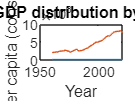

clear; close all;
% Conectar con web api.
conn = wb();

%  Importar data del pib per capital con los filtros sql necesarios
gdp_data = query(conn,'source','2',...
    'series','NY.GDP.PCAP.KN',...
    'country','CHL',...
    'time','all');

% Traer tabulado
raw_data = {gdp_data.source.data.value};

% Manipular datos
PIB = flip(transpose(raw_data));
year = [1960:2020]';
PIB = [ year cell2mat(PIB)];

% Grafico para explorar datos 
figure(12)
plot(year,PIB)
% Create ylabel
ylabel({'GDP per capita (constant LCU)'})
% Create xlabel
xlabel({'Year'})
% Create title
title({'Figure 5. GDP distribution by year in Chile'})
hold off

(d) Obtenga a tendencia y el ciclo de la serie utilizando el filtro Hodrick-Prescott estudiado en preguntas anteriores. Puede reutilizar las funciones creadas previamente si lo desea.

Se utilizará el filtro construido en la pregunta anterior, junto con graficar las tendencias según distintos niveles de sensibilidad. 

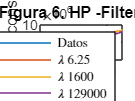

lambda = [6.25 1600 129000];
% Dado que no se recomienda renombrar dinámicamente en matlab se crea cada
% objeto a mano
[ytrend625, ycycle625] = hp_filter(PIB,lambda(1));
[ytrend16, ycycle16] = hp_filter(PIB,lambda(2));
[ytrend129, ycycle129] = hp_filter(PIB,lambda(3));
graph = [PIB(:,2) ytrend625(:,2) ytrend16(:,2) ytrend129(:,2)]; % Matriz con variables de cobre
hpfigure(graph) % Grafico 

(e) Mediante OLS, compute el coeficiente autoregresivo ausmiendo que la serie sigue un proceso AR(1). 

% Dimensiones
y = ytrend625(1:end,2);
X = y(1:end-1);
y = y(2:end);

% OLS and statistics
n = length(y);
k = 2;
X = [ones(length(X), 1) X];
beta = (X\y)';
e = y - X.*beta;
s2 = e'*e/ (n-k);
se = sqrt(s2*diag(inv(X'*X)));
t = beta./se;
rmse = sqrt(s2);
p = 2*(1-tcdf(abs(t), length(y) - k));

Tal como aparecen en los outputs el $\hat{\phi} \approx 1\ldotp 01378$, valor que fue rectificado con la función $\textrm{fitlm}\ldotp$ En base a la discusión que presentamos anteriormente, podremos notar que la función de impulso respuesta en este caso dependendería principalmente de $\delta \ldotp$ Ahora profundizaremos para esta tendencia que incidencia tiene distintos niveles de persistencia sobre la función de impulso respuesta. 

(f) Compute una IRF asumiendo un shock transitorio $\epsilon =1$ en t=0 sobre el residuo de la serie

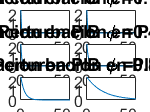

phi = [0.1 0.2 0.4 0.6 0.8 0.95]'; % persistencia
time = length(y); %60 periodos
error = randn(time,1); % mean = 0, sd = 1
y2 = y ;
for i = 1:6
    y(1) = 0 + error(1);
    for t = 2:time
        y(t)= phi(i)*y(t-1) + error(t);
    end
    y2(1) = 0 + 1; % shock 1
    for t = 2:time
        y2(t)= phi(i)*y2(t-1) + error(t);
    end
figure(15)
subplot(3,2,i)    
plot(y2-y)
title(['Perturbacion en PIB \phi =', num2str(phi(i))])
hold off
end

(g) ¿Cómo cambian los resultados al variar la persistencia del proceso? Grafique y explique

En el punto anterior generamos un algoritmo que permitió obtener la función de impulso respuesta, esto es, $\triangle y=y_{\epsilon =1} -y_{\epsilon ~N\left(0,\sigma^2 \right)}$, es decir, la comparación entre la tendencia del PIB con un shock transitorio y el PIB con su serie filtrada con HP filter. Como discutimos anteriormente, si el proceso puede ser modelado a partir de un ARIMA se cumplirán tres propiedades

- History independence property

- Linearity

-  Symmetry

Hasta ahora hemos podido abordar las primeras dos, toda vez que refieren a la relación que tienen las variables endógenas con su pasado y la diferencia que producen diferentes niveles de persistencia. Ahora bien, en este apartado avanzaremos hacia una discusión más analítica. Lo interesante de este ejercicio es notar que una vez que se desestacionaliza la serie de PIB, si comparamos el PIB sin shock transitorio y con shock transitorio (IRF) obtendremos que su capacidad de respuesta dependerá del $\phi$. Cuando la serie es débilmente persistente, la recuperación respecto al shock es bastante rápida, mientras que cuando la perturbación es más grande  ($\left.\phi \approx 0\ldotp 95\right)$la recuperación es más lenta. Como podemos ver en las figuras, incluso en 60 años de serie, sigue existiendo un ruído de este shock. El resultado no es trivial: en el apartado anterior llegamos a la conclusión de que $\hat{\phi} \approx 1\ldotp 01378$ por lo que la IRF dado el shock transitorio podría perdurar durante un tiempo.  Ahora bien, es probable que estos resultados cambien si en esta estimación de igual manera incluimos el efecto del ciclo. Mejoras en el análisis podrían incluir, en este caso, la inclusión de medias móviles y análisis de cointegración dada la tendencia de la serie. 

(h) ¿Cómo cambian los resultados anteriores al variar la manitud del shock transitorio? Grafique y explique.

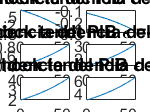

shock = [-2 -1 -0.5 0.5 1 2]'; % persistencia
time = length(y); %60 periodos
phi = 1.01378;
error = randn(time,1); % mean = 0, sd = 1
y2 = y ;
for i = 1:6
    y(1) = 0 + error(1);
    for t = 2:time
        y(t)= phi*y(t-1) + error(t);
    end
    y2(1) = 0 + shock(i); % shock 1
    for t = 2:time
        y2(t)= phi*y2(t-1) + error(t);
    end
figure(16)
subplot(3,2,i)    
plot(y2-y)
title(['Shock tendencia del PIB \epsilon =', num2str(shock(i))])
hold off
end

Con este último ejercicio demostramos una de las propiedades que habíamos destacado: los modelos AR(1) y ARIMA tienen funciones de impulso respuesta tienen la propiedad de ser **siméticas ** (esto es, un shok en 1 tiene un efecto exactamente opuesto a un shock -1). Notemos que el subplot del shock de -2 y 2 son simétricos, así cada uno correspondientemente. Entonces, si bien antes discutimos sobre la **magnitud de la persistencia y su relación con el proceso autoregresivo **(esto es, la propiedad lineal y de independencia, respectivamente), ahora podemos mostrar que también se cumple la propiedad de simetría. Como señalaron Koop (1996, p. 123)  en *"Impulse response analysis in nonlinear multivariate models"  *este tipo de propiedades son tradicionales a las funciones de impulso respuesta, y que incluso han sido probadas empíricamente en investigaciones clásicas como las de Campbell y Mankiw (1987) cuando normalizaron el $\delta$ (el que nos da el nivel o escala del shock). 

En relación al resultado obtenido respecto del PIB, evidentemente existe un sesgo en el resultado dado la desestacionalización de la serie, y de que asumimos un modelamiento lineal. De hecho, en nuestros resultado ya podemos ver algunos problemas, toda vez que la persistencia no resulta significativa en toda la serie, por lo que probablemente se deban explorar otros modelos probabilísticos que se adequen mejor la la forma de la distribución. Entonces, si bien la simetría es evidente y cumple con la versión tradicional de IRF, este resultado se da **dado que elegimos un modelamiento lineal. **Como mencionan investigaciones posteriores, el modelamiento del PIB puede tener como resultado asimetrías en la medida en que se recosnidera el modelamiento hacia uno no lineal y que considera el ciclo de la serie (véase  en Cancelo y Mourelle, 2005)

Ahora bien, no siempre estas propiedades se mantienen en modelos no lineales, dado que esto también dependerá del signo de la IRF, pues en algunos casos shocks positivos no producirán cambios positivos, y con ello la propiedad de simetría se perderá y el modelamiento sobre el futuro se hará más difícil (encontrar un contrafactual perfecto), y la dependencia del shock y pasado serán problemas. 

## Referencias

Cancelo, J. R., & Mourelle, E. (2005). Modeling cyclical asymmetries in GDP: international evidence. *Atlantic Economic Journal*, *33*(3), 297-309.

Koop, G., Pesaran, M. H., & Potter, S. M. (1996). Impulse response analysis in nonlinear multivariate models. *Journal of econometrics*, *74*(1), 119-147.

Sargent, T. J., & Ljungqvist, L. (2000). Recursive macroeconomic theory. *Massachusetss Institute of Technology*.

Stokey, N. L. (1989). *Recursive methods in economic dynamics*. Harvard University Press.